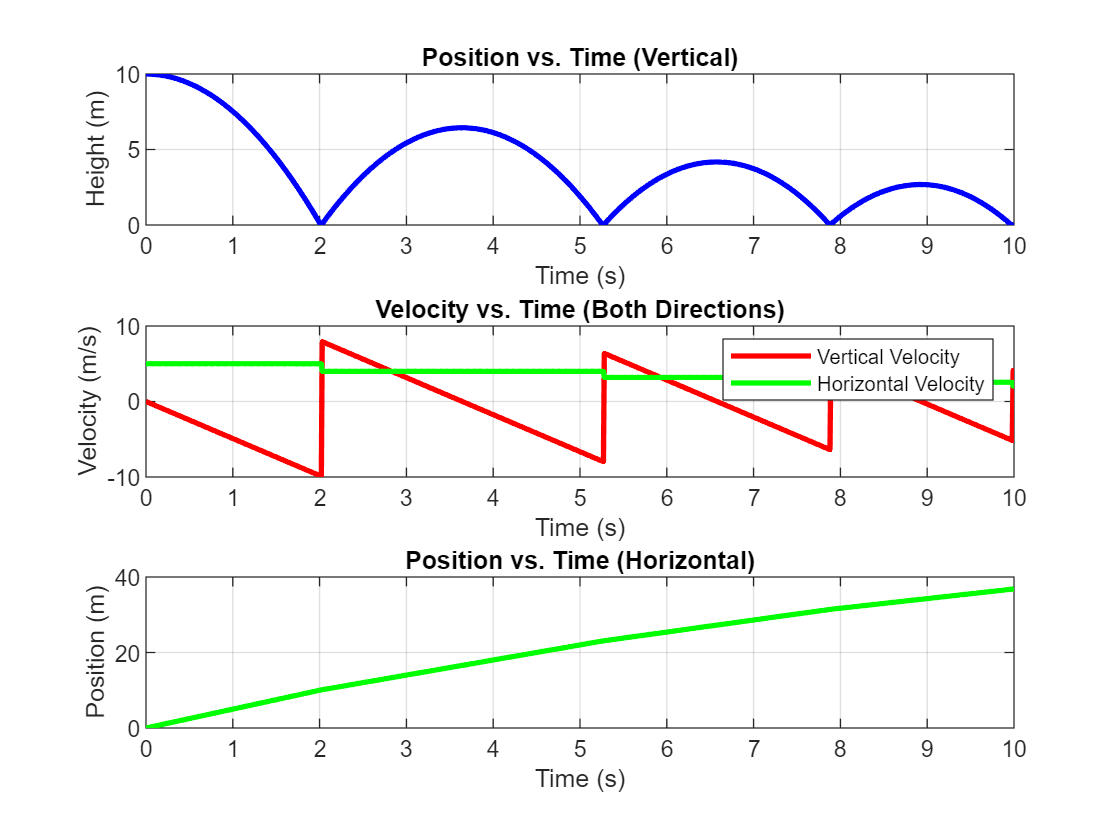

% Bouncing ball simulation in 2D with x-axis motion and drag force
clear
clf

% Parameters
g = 9.81; % acceleration due to gravity (m/s^2)
e = 0.8; % coefficient of restitution of ball
dt = 0.01; % time step (s)
total_time = 10; % total simulation time (s)
y0 = 10; % initial height of the ball (m)
v0x = 5; % initial velocity in x-direction (m/s)
v0y = 0; % initial velocity in y-direction (m/s)
x0 = 0; % initial position in x-direction (m)
m = 0.5; % mass (kg)
r = 0.005; % radius (m)
A = pi*(r^2); % cross section area (m^2)
rho = 1.293; % air density (kg/m^3)
C = 0.43; % drag coeff

% Initialization
t = 0:dt:total_time;
n_steps = numel(t);
y = zeros(1, n_steps);
v_x = zeros(1, n_steps);
v_y = zeros(1, n_steps);
x = zeros(1, n_steps);

% Initial conditions
y(1) = y0;
v_x(1) = v0x;
v_y(1) = v0y;
x(1) = x0;

for i = 2:n_steps
    % Update velocity
    if y(i-1) <= 0
        v_x(i) = e * v_x(i-1); % Horizontal velocity remains constant after bounce
        v_y(i) = -e * v_y(i-1); % Vertical velocity changes direction after bounce
    else
        % Calculate drag force
        v_mag = sqrt(v_x(i-1)^2 + v_y(i-1)^2);
        F_drag_x = -0.5 * rho * A * C * v_x(i-1) * v_mag;
        F_drag_y = -0.5 * rho * A * C * v_y(i-1) * v_mag;
        
        % Update velocity with drag force
        v_x(i) = v_x(i-1) + (F_drag_x / m) * dt;
        v_y(i) = v_y(i-1) + ((-m * g) + (F_drag_y / m)) * dt;
    end
    
    % Update height
    y(i) = y(i-1) + v_y(i) * dt;
    
    % Ball hits the ground
    if y(i) <= 0
        y(i) = 0; % Prevent ball from going below ground
    end

    % Update position in x-direction
    x(i) = x(i-1) + v_x(i) * dt;
end

% Plot position vs. time
subplot(3,1,1);
plot(t, y, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Height (m)');
title('Position vs. Time (Vertical)');
grid on

% Plot velocity vs. time
subplot(3,1,2);
plot(t, v_y, 'r', 'LineWidth', 2);
hold on;
plot(t, v_x, 'g', 'LineWidth', 2);
hold off;
legend('Vertical Velocity', 'Horizontal Velocity');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time (Both Directions)');
grid on

% Plot position vs. time
subplot(3,1,3);
plot(t, x, 'g', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Position (m)');
title('Position vs. Time (Horizontal)');

grid on